# 

# Estimación de la cinética de una reacción química

Hermes Pantoja Carhuavilca, Victor Anhuaman, Daniel Camarena, Jimmy Miranda, rósulo pérez, Máximo Obregón. 

Departamento de Ciencias, Universidad de Ingeniería y Tecnología (UTEC) 

## Integrantes

Nombres de los integrantes y el porcentaje de participación:

- Apellidos, nombres (100 %)

- Apellidos, nombres (Líder, 90 %)

- Apellidos, nombres (100 %)

- Apellidos, nombres (85 %)

## Objetivo de la actividad:

Analizar el impacto de las bondades del método de mínimos cuadrados para estimar la constante de velocidad de reacción a partir de datos experimentales. Esta actividad permitirá a los estudiantes aplicar el método de mínimos cuadrados en el contexto de un problema de cinética química.

## Contexto y escenario del problema:

Como parte del equipo de diseño para un nuevo proyecto de construcción, se requiere realizar un análisis preliminar de las vigas que formarán parte de la estructura de soporte de un edificio. Dado que las propiedades de los materiales y las cargas pueden tener variaciones, es crucial entender cómo estas incertidumbres afectan la seguridad y viabilidad del diseño. 

En una planta química dedicada a la producción de papel, el peróxido de hidrógeno ($\text{H}_2\text{O}_2$) se utiliza como agente blanqueador debido a su alta eficiencia y capacidad de oxidación. Sin embargo, su descomposición en condiciones de extrema alcalinidad y altas temperaturas es una preocupación importante. Para optimizar el proceso de blanqueo y mejorar la eficiencia del uso de $\text{H}_2\text{O}_2$, se ha llevado a cabo una serie de experimentos en el laboratorio de la planta química para estudiar la cinética de su descomposición.

Se realizaron experimentos a tres temperaturas distintas (90°C, 110°C y 130°C) y con una concentración de 4% de hidróxido de sodio ($\text{NaOH}$). Durante estos experimentos, se midieron las concentraciones de $\text{H}_2\text{O}_2$ a intervalos regulares de tiempo. Los datos experimentales obtenidos se muestran en la Tabla 1.


$$\begin{array}{|c|c|c|c|c|c|c|c|c|c|c|c|c|c|c|}\hline \text { Ensayos } & \text { Tiempo (s) } & 0 & 300 & 600 & 900 & 1200 & 1500 & 1800 & 2100 & 2400 & 2700 & 3000 & 3300 & 3600 \\\hline \text { Temperatura } 90^{\circ} \mathrm{C} & \mathrm{H}_2 \mathrm{O}_2(\mathrm{~mol} / \mathrm{L}) & 0.16 & 0.16 & 0.16 & 0.16 & 0.16 & 0.15 & 0.15 & 0.15 & 0.15 & 0.15 & 0.15 & 0.15 & 0.15 \\\hline 4 \% \mathrm{NaOH}(0.13 \mathrm{~mol} / \mathrm{L}) & \mathrm{pH} & 12.50 & 12.60 & 13.10 & 12.90 & 12.80 & 12.50 & 12.40 & 12.80 & 12.40 & 12.40 & 12.90 & 13.10 & 12.90 \\\hline \text { Temperatura } 110^{\circ} \mathrm{C} & \mathrm{H}_2 \mathrm{O}_2(\mathrm{~mol} / \mathrm{L}) & 0.16 & 0.15 & 0.15 & 0.15 & 0.13 & 0.13 & 0.12 & 0.12 & 0.12 & 0.12 & 0.12 & 0.12 & 0.12 \\\hline 4 \% \mathrm{NaOH}(0.14 \mathrm{~mol} / \mathrm{L}) & \mathrm{pH} & 11.57 & 11.56 & 11.59 & 11.82 & 12.05 & 12.41 & 12.47 & 12.46 & 12.49 & 12.50 & 12.59 & 12.48 & 12.33 \\\hline \text { Temperatura } 130^{\circ} \mathrm{C} & \mathrm{H}_2\mathrm{O}_2(\mathrm{~mol} / \mathrm{L}) & 0.16 & 0.15 & 0.15 & 0.15 & 0.13 & 0.13 & 0.12 & 0.12 & 0.12 & 0.12 & 0.12 & 0.12 & 0.12 \\\hline 4 \% \mathrm{NaOH}(0.14 \mathrm{~mol} / \mathrm{L}) & \mathrm{pH} & 12.05 & 12.06 & 12.07 & 12.54 & 12.90 & 12.97 & 12.94 & 12.99 & 12.95 & 12.96 & 12.90 & 12.97 & 12.88 \\\hline\end{array}$$


Table 1: Concentraciones de $\mathrm{NaOH}, \mathrm{H}_2 \mathrm{O}_2$ y valores de pH a lo largo del tiempo para los experimentos con $4 \%$ de NaOH a distintas temperaturas.

Como estudiante de métodos numéricos, se te ha asignado la tarea de calcular la energía de activación de la reacción de descomposición del $\text{H}_2\text{O}_2$ en el laboratorio de la planta química. La energía de activación se puede calcular utilizando la ecuación de Arrhenius:


$$k = A e^{-\frac{E_a}{RT}}$$


Donde:

- $k$ es la constante cinética específica,

- $A$ es el factor preexponencial,

- $E_a$ es la energía de activación,

- $R$ es la constante universal de los gases (8.314 J/mol·K),

- $T$ es la temperatura en Kelvin.

Para hallar los valores de la constante cinética específica ($k$) se halla a partir de los valores de la constante cinética aparente según la relación:


$$k = \frac{k'}{[\text{NaOH}]}.$$
 

Los valores de la constante cinética aparente ($k'$), se deben calcular a partir de los datos experimentales considerando el modelo de reacción de orden 0:


$$[\text{H}_2\text{O}_2] = [\text{H}_2\text{O}_2]_0 - k't,$$


donde:

- $[\text{H}_2\text{O}_2]_0$ es la concentración inicial de peróxido de hidrógeno.

- $t$ es el tiempo.

### Constantes cinéticas aparentes 

-  Determinar las constantes cinéticas aparentes $k'$: Utiliza los datos de concentración de $\text{H}_2\text{O}_2$ a lo largo del tiempo para cada temperatura y calcula la constante cinética aparente $k'$ para cada temperatura, asumiendo una reacción de orden cero.

% Datos de tiempo (en segundos)
t = [0 300 600 900 1200 1500 1800 2100 2400 2700 3000 3300 3600]';

% Concentraciones de H2O2 para diferentes temperaturas (en mol/L)
conc_H2O2_90 = [0.16 0.16 0.16 0.16 0.16 0.15 0.15 0.15 0.15 0.15 0.15 0.15 0.15]';
conc_H2O2_110 = [0.16 0.15 0.15 0.15 0.13 0.13 0.12 0.12 0.12 0.12 0.12 0.12 0.12]';
conc_H2O2_130 = [0.16 0.15 0.15 0.15 0.13 0.13 0.12 0.12 0.12 0.12 0.12 0.12 0.12]';

% Cálculo de las constantes cinéticas aparentes (k')
k_prime_90 = polyfit(t, conc_H2O2_90, 1);
k_prime_110 = polyfit(t, conc_H2O2_110, 1);
k_prime_130 = polyfit(t, conc_H2O2_130, 1);

% Extracción de las pendientes (k') para cada temperatura
k_prime_90_value = -k_prime_90(1)

k_prime_90_value =      3.663003663003669e-06


k_prime_110_value = -k_prime_110(1)

k_prime_110_value =      1.153846153846155e-05


k_prime_130_value = -k_prime_130(1)

k_prime_130_value =      1.153846153846155e-05


### Constantes cinéticas específicas 

-  Calcular las constantes cinéticas específicas $k$: Una vez obtenidas las constantes cinéticas aparentes, calcula las constantes cinéticas específicas utilizando la siguiente relación:

             
$$k = \frac{k'}{[\text{NaOH}]}$$


            donde $[\text{NaOH}]$ para una solución al 4% de $\text{NaOH}$ depende de la temperatura y se indica en la tabla de datos.

            A partir de estos valores, y considerando los valores de temperatura construya una tabla de datos para le Ecuación de Arrhenius.

% Concentraciones de NaOH (en mol/L)
conc_NaOH_90 = 0.13;
conc_NaOH_110 = 0.14;
conc_NaOH_130 = 0.14;

% Cálculo de las constantes cinéticas específicas
k_90 = k_prime_90_value / conc_NaOH_90

k_90 =      2.817695125387438e-05


k_110 = k_prime_110_value / conc_NaOH_110

k_110 =      8.241758241758249e-05


k_130 = k_prime_130_value / conc_NaOH_130

k_130 =      8.241758241758249e-05


### Ecuación de Arrhenius

- Ajuste de la Ecuación de Arrhenius: Linealiza la ecuación de Arrhenius para poder ajustar los datos experimentales y determinar el ajuste lineal así como su bondad de ajuste.

### Energía de Activación 

- Cálculo de la Energía de Activación: A partir del ajuste lineal de la ecuación de Arrhenius, determina la pendiente y calcula la energía de activación $E_a$.

% Conversión de temperaturas a Kelvin
temps_C = [90, 110, 130];  % Temperaturas en °C
temps_K = temps_C + 273.15;  % Temperaturas en K

% Logaritmo de las constantes cinéticas específicas
ln_k = log([k_90, k_110, k_130]);

% Inverso de las temperaturas en Kelvin
inv_T = 1 ./ temps_K;

% Ajuste lineal de ln(k) vs 1/T
ajuste_Arrhenius = polyfit(inv_T, ln_k, 1);
pendiente = ajuste_Arrhenius(1)

pendiente =     -3.993088410338451e+03


interseccion = ajuste_Arrhenius(2)

interseccion =    0.679242710119730



% Constante universal de los gases (en J/(mol·K))
R = 8.314;

% Cálculo de la energía de activación (en J/mol)
E_a = -pendiente * R

E_a =      3.319853704355388e+04


### Visualización de análisis

- Realice gráficos (en MatLab) para acompañar los análisis y cálculos hechos e interprete cada gráfica.

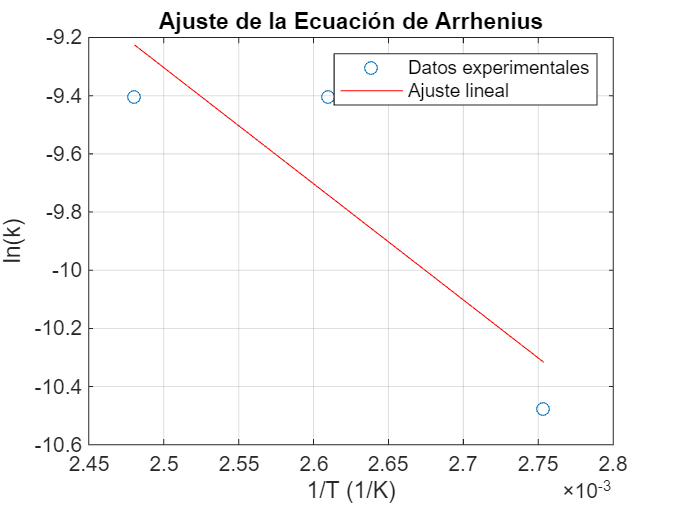

% Gráfico de ln(k) vs 1/T con el ajuste lineal
plot(inv_T, ln_k, 'o', 'DisplayName', 'Datos experimentales');
hold on;
plot(inv_T, polyval(ajuste_Arrhenius, inv_T), '-r', 'DisplayName', 'Ajuste lineal');
xlabel('1/T (1/K)');
ylabel('ln(k)');
legend show;
title('Ajuste de la Ecuación de Arrhenius');
grid on;


% Cálculo de R^2
ln_k_fit = polyval(ajuste_Arrhenius, inv_T);
SS_res = sum((ln_k - ln_k_fit).^2);
SS_tot = sum((ln_k - mean(ln_k)).^2);
R2 = 1 - (SS_res / SS_tot);

fprintf('Energía de activación: %f J/mol\n', E_a);

Energía de activación: 33198.537044 J/mol


fprintf('R^2 del ajuste: %f\n', R2);

R^2 del ajuste: 0.775622


### **Interpretación de Resultados**

El resultado final incluye la energía de activación calculada, el valor de $R^2$ que indica la calidad del ajuste, y una visualización gráfica que muestra el comportamiento de los datos respecto al ajuste de Arrhenius.

## Referencias

- Chapra, S. C. (2012). *Applied numerical methods*. Columbus: McGraw-Hill.

- Dahlquist, G., & Björck, Å. (2003). *Numerical methods*. Courier Corporation.